## Testing on Real Data

Test the LCC workflow on actual Lidar data to evaluate its performance.

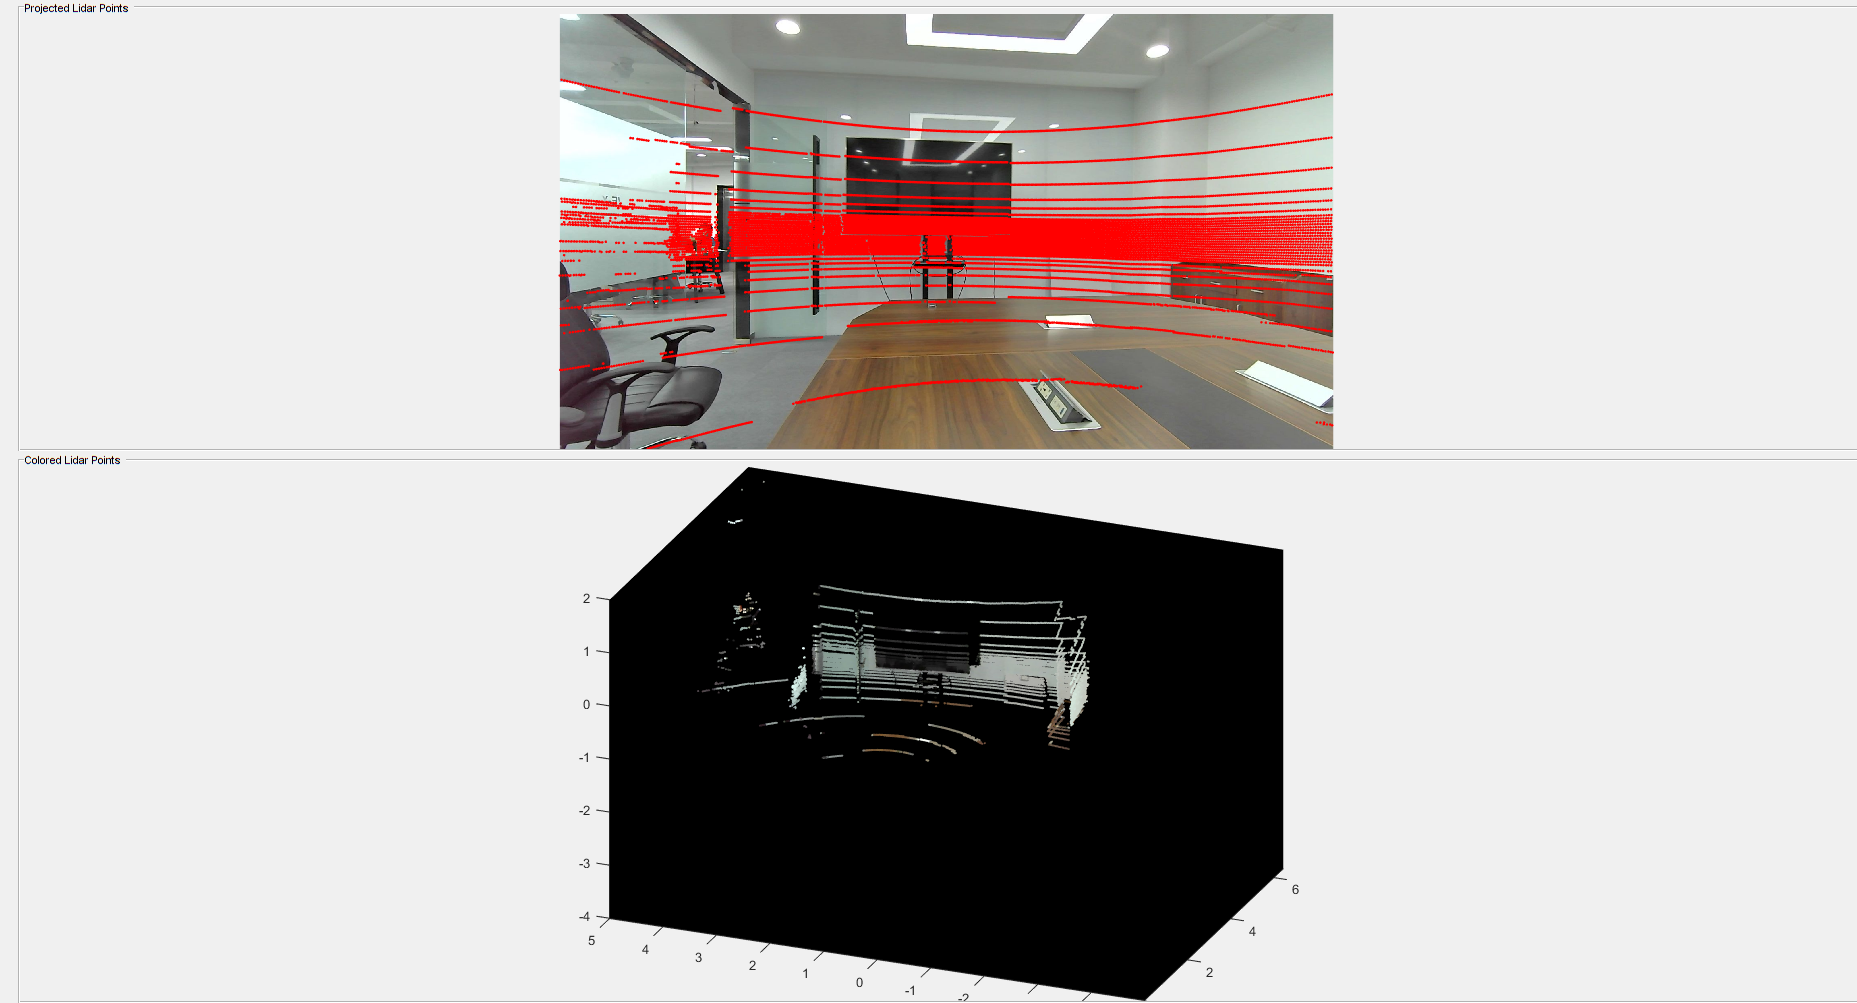

test_image_path = fullfile('lcc', 'RawImages');
test_pointcloud_path = fullfile('lcc', 'PointClouds');

imds = imageDatastore(test_image_path); % Load images using imageDatastore
pcds = fileDatastore(test_pointcloud_path, 'ReadFcn', @pcread); % Loadr point cloud files

test_image_file_names = imds.Files;
test_point_cloud_file_names = pcds.Files;

helperFuseFullLidarCamera(test_image_file_names, test_point_cloud_file_names, cameraParams, tform);